%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


pose_f = [0 1 0];
E_max = 300;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

phi_ddot_max = 55;

% solve
dt = 0.001;
options = optimoptions("fmincon",...
    "Algorithm","interior-point",...
    "SubproblemAlgorithm","cg",...
    "ConstraintTolerance",0.001);
[solution,objectiveValue,exitflag] = fmincon(@(optimInput)objectiveFcn(optimInput),4,[],[],[],[],[],[],...
    @(optimInput)constraintFcn(optimInput, phi_ddot_max, pose_f, dt, E_max),options);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% The optimisation sometimes doesnt get close to 300 J;
% if so, the timescale can be manually reduced until the energy consumption is close to 300 J
timescale = solution;

[t_3, xt, yt, psi, v, omega, phi_dot, V, i, P, E] = generateTrapezoidal(phi_ddot_max, timescale, pose_f, dt);

T_f = t_3

t_f = 6.5430


E

E = 162.3954

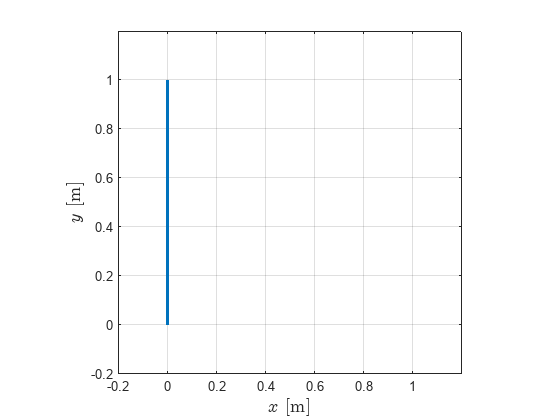


t = 0:dt:T_3;

figure(2), clf
plot(xt, yt, LineWidth=2)
pbaspect([1 1 1])
xlim([-0.2 1.2])
ylim([-0.2 1.2])
xlabel("$x$ [m]",fontsize=14, Interpreter="latex")
ylabel("$y$ [m]",fontsize=14, Interpreter="latex")
grid on
set(gca, 'xtick', -0.4:0.2:1.6)
set(gca, 'ytick', -0.4:0.2:1.6)

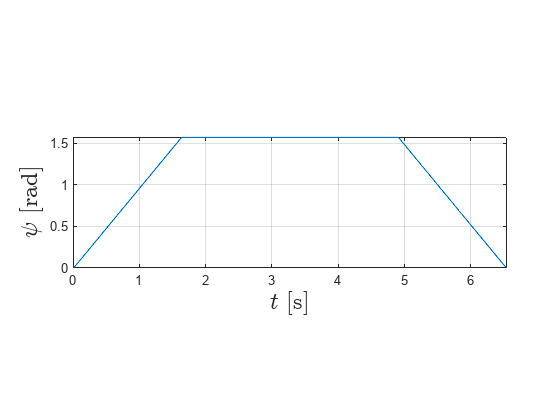


figure(3), clf
plot(t, psi)
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=18, Interpreter="latex")
ylabel("$\psi$ [rad]",fontsize=18, Interpreter="latex")
xlim([0 t_f])
grid on

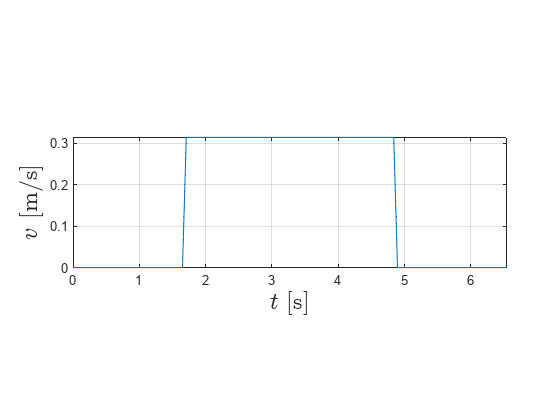


figure(4),clf
plot(t, v)
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=18, Interpreter="latex")
ylabel("$v$ [m/s]",fontsize=18, Interpreter="latex")
xlim([0 t_f])
grid on

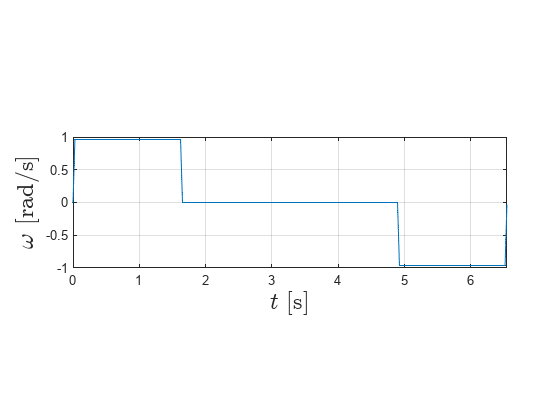


figure(5), clf
plot(t, omega)
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=18, Interpreter="latex")
ylabel("$\omega$ [rad/s]",fontsize=18, Interpreter="latex")
xlim([0 t_f])
grid on

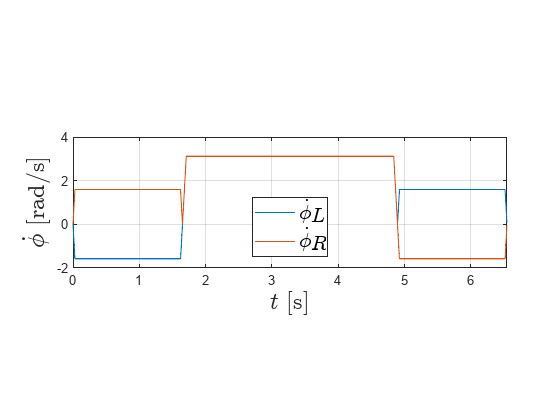


figure(6), clf
plot(t, phi_dot(1,:), t, phi_dot(2,:))
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=18, Interpreter="latex")
ylabel("$\dot{\phi}$ [rad/s]",fontsize=18, Interpreter="latex")
xlim([0 t_f])
legend("$\dot{\phi}_{L}$","$\dot{\phi}_R$",Interpreter="latex",fontsize=16, Location="south")
grid on

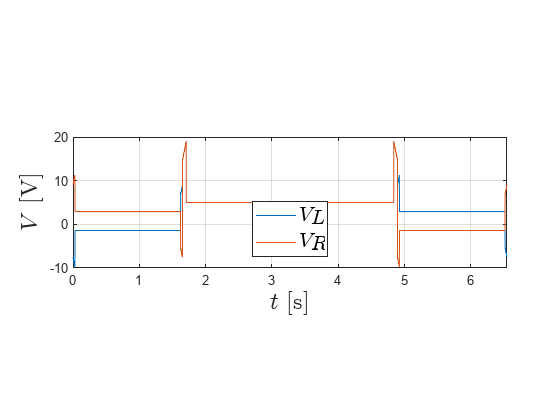


figure(7), clf
plot(t,V(1,:), t, V(2,:))
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=18, Interpreter="latex")
ylabel("$V$ [V]",fontsize=18, Interpreter="latex")
xlim([0 t_f])
legend("$V_L$","$V_R$",Interpreter="latex", fontsize=16, Location="south")
grid on

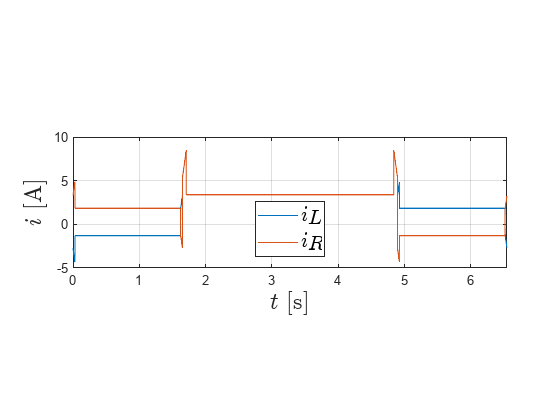


figure(8), clf
plot(t,i(1, :), t, i(2,:))
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=18, Interpreter="latex")
ylabel("$i$ [A]",fontsize=18, Interpreter="latex")
xlim([0 t_f])
legend("$i_L$","$i_R$",Interpreter="latex", fontsize=16, Location="south")
grid on

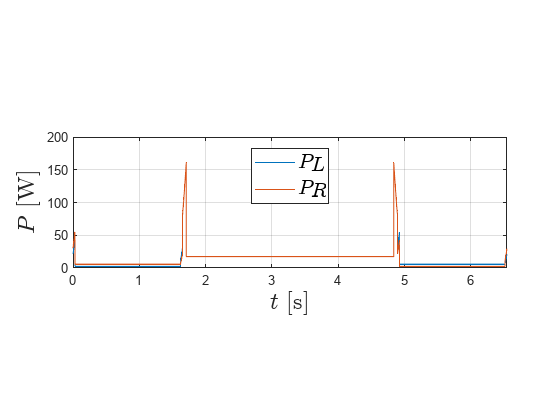


figure(9), clf
plot(t, P(1,:), t, P(2,:))
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=18, Interpreter="latex")
ylabel("$P$ [W]",fontsize=18, Interpreter="latex")
xlim([0 t_f])
legend("$P_{L}$","$P_R$",Interpreter="latex", fontsize=16, Location="north")
grid on

function f = objectiveFcn(optimInput) % Cost function to be minimised
timescale = optimInput(1);

f = timescale;
end

% Constraint function containing energy constraints and motor limits
function [c,ceq] = constraintFcn(optimInput, phi_ddot_max, pose_3, dt, E_max)
timescale = optimInput(1);

[~, ~, ~, ~, ~, ~, ~, V, ~, ~, E] = generateTrapezoidal(phi_ddot_max, timescale, pose_3, dt);

c(1) = -timescale+1;
c(2) = E-E_max;
c(3) = max(max(V(1,:)), max(V(2,:))) - 24;

ceq = [];
end

% Function to generate the trajectory and calculate energy consumption
function [t_3, x, y, psi, v, omega, phi_dot, V, i, P, E] = generateTrapezoidal(phi_ddot_max, timescale, pose_3, dt)
% Robot physical dimentions
r = 0.1;      % wheel radius
d = 0.33;       % wheelbase
l = d/2;          % Distance from wheels to axis of symmetry
c = r/(2*l);    % Geometric constant

% DC motor constants
Tm = 0.359;         % Constant friction torque
n = 19.7;              % gear ratio
Kt = 0.069;         % torque constant
Kv = 0.069;         % voltage constant
R = 2.74;              % armature resistance
upsilon = 0.0017;    % viscous damping coefficient

% Robot system masses
m_c = 21.2;         % Body mass (no wheels or motor rotors)
m_w = 1.39;         % 1 Wheel and rotor mass
m = m_c + 2*m_w;    % total robot mass

% Robot system moments of inertia
I_c = (1/2)*m_c*l^2;                            % Robot body (no wheels or motor rotors)
I_w = (1/2)*m_w*r^2;                            % Wheels about rotation axis
I_m = (1/4)*m_w*r^2 + (1/12)*m_w*(0.02^2);      % Wheels about diameter
I_s = 0.000026127698;                           % equivalent of motors
I = I_c + 2*m_w*l^2 + 2*I_m;                    % total

% Matrices that remain constant
T = [   0       0;
        0       0;
        Kt*n/R  0;
        0       Kt*n/R];

M = [   m       0       0                   0;
        0       m       0                   0;
        0       0       (I*c^2)+I_w+I_s    -I*c^2;
        0       0       -I*c^2              (I*c^2)+I_w+I_s];

F = [   0       0       0                           0;
        0       0       0                           0;
        0       0       ((Kt*Kv*n^2)/(R))+upsilon   0;
        0       0       0                           ((Kt*Kv*n^2)/(R))+upsilon];

C = [0;0;Tm;Tm];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

pose_0 = [0 0 0];

v_dot_max = phi_ddot_max*r;
omega_dot_max = phi_ddot_max*(2*r)/(d);

x_3 = pose_3(1);
y_3 = pose_3(2);
psi_3 = pose_3(3);

x_2 = pose_3(1);
y_2 = pose_3(2);
psi_2 = atan2(y_3,x_3);

x_1 = pose_0(1);
y_1 = pose_0(2);
psi_1 = psi_2;

x_0 = pose_0(1);
y_0 = pose_0(2);
psi_0 = pose_0(3);

x_ddot_max = v_dot_max*cos(psi_1);
y_ddot_max = v_dot_max*sin(psi_1);

t_1 = timescale*(sqrt((4*abs(psi_1-psi_0))/omega_dot_max) + 0.0001);    % phase 1 time at completion
t_2 = t_1 + timescale*(sqrt((4*sqrt((x_2-x_1)^2 + (y_2-y_1)^2))/v_dot_max) + 0.0001);   % phase 2 time at completion
t_3 = t_2 + timescale*(sqrt((4*abs(psi_3-psi_2))/omega_dot_max) + 0.0001);   % phase 3 time at completion

t_c1 = (t_1/2) - (1/2)*sqrt(((omega_dot_max*t_1^2) - 4*(psi_1-psi_0))/(omega_dot_max));
t_c2 = ((t_2-t_1)/2) - (1/2)*sqrt(((v_dot_max*(t_2-t_1)^2) - 4*(sqrt((x_3-x_0)^2 + (y_3-y_0)^2)))/(v_dot_max));
t_c3 = ((t_3-t_2)/2) - (1/2)*sqrt(((omega_dot_max*(t_3-t_2)^2) - 4*(abs(psi_3-psi_2)))/(omega_dot_max));

t = 0:dt:t_3;

x = zeros([1, length(t)]);
x_dot = zeros([1, length(t)]);
x_ddot = zeros([1, length(t)]);
y = zeros([1, length(t)]);
y_dot = zeros([1, length(t)]);
y_ddot = zeros([1, length(t)]);
psi = zeros([1, length(t)]);
omega = zeros([1, length(t)]);
omega_dot = zeros([1, length(t)]);


for i=1:length(t)
    if t(i) < t_1       % PHASE 1 - ROTATION
        x(i) = x_0;
        y(i) = y_0;
        
        dds_max = sign(psi_1-psi_0)*omega_dot_max;

        if t(i) < t_c1
            psi(i) = psi_0 + (1/2)*dds_max*t(i)^2;
            omega(i) = dds_max*t(i);
            omega_dot(i) = dds_max;
        elseif t(i) < t_1-t_c1
            psi(i) = psi_0 + dds_max*t_c1*(t(i)-(t_c1/2));
            omega(i) = dds_max*t_c1;
            omega_dot(i) = 0;
        else
            psi(i) = psi_1 - 1/2*dds_max*(t_1-t(i))^2;
            omega(i) = dds_max*t_c1 - dds_max*(t(i)-(t_1-t_c1));
            omega_dot(i) = -dds_max;
        end

    elseif t(i) < t_2   % PHASE 2 - TRANSLATION
        psi(i) = psi_2;

        if t(i) < t_1 + t_c2
            x(i) = x_1 + (1/2)*x_ddot_max*(t(i)-t_1)^2;
            x_dot(i) = x_ddot_max*(t(i)-t_1);
            x_ddot(i) = x_ddot_max;
            y(i) = y_1 + (1/2)*y_ddot_max*(t(i)-t_1)^2;
            y_dot(i) = y_ddot_max*(t(i)-t_1);
            y_ddot(i) = y_ddot_max;
        elseif t(i) < t_2-t_c2
            x(i) = x_1 + x_ddot_max*t_c2*(t(i)-t_1-(t_c2/2));
            x_dot(i) = x_ddot_max*t_c2;
            x_ddot(i) = 0;
            y(i) = y_1 + y_ddot_max*t_c2*(t(i)-t_1-(t_c2/2));
            y_dot(i) = y_ddot_max*t_c2;
            y_ddot(i) = 0;
        else
            x(i) = x_2 - 1/2*x_ddot_max*((t_2-t_1)-(t(i)-t_1))^2;
            x_dot(i) = x_ddot_max*t_c2 - x_ddot_max*((t(i)-t_1) - ((t_2-t_1)-t_c2));
            x_ddot(i) = -x_ddot_max;
            y(i) = y_2 - 1/2*y_ddot_max*((t_2-t_1)-(t(i)-t_1))^2;
            y_dot(i) = y_ddot_max*t_c2 - y_ddot_max*((t(i)-t_1) - ((t_2-t_1)-t_c2));
            y_ddot(i) = y_ddot_max;
        end
    else                % PHASE 3 - ROTATION
        x(i) = x_3;
        y(i) = y_3;

        dds_max = sign(psi_3-psi_2)*omega_dot_max;

        if t(i) < t_2 + t_c3
            psi(i) = psi_2 + (1/2)*dds_max*(t(i)-t_2)^2;
            omega(i) = dds_max*(t(i)-t_2);
            omega_dot(i) = dds_max;
        elseif t(i) < t_3-t_c3
            psi(i) = psi_2 + dds_max*t_c3*((t(i)-t_2)-(t_c3/2));
            omega(i) = dds_max*t_c3;
            omega_dot(i) = 0;
        else
            psi(i) = psi_3 - 1/2*dds_max*((t_3-t_2)-(t(i)-t_2))^2;
            omega(i) = dds_max*t_c3 - dds_max*((t(i)-t_2)-((t_3-t_2)-t_c3));
            omega_dot(i) = -dds_max;
        end
    end
end

v = sqrt((x_dot.^2) + (y_dot.^2));
v_dot = sqrt((x_ddot.^2) + (y_ddot.^2));
phiL_dot = (v/r) - (d*omega/(2*r));
phiR_dot = (v/r) + (d*omega/(2*r));
phiL_ddot = (v_dot/r) - (d*omega_dot/(2*r));
phiR_ddot = (v_dot/r) + (d*omega_dot/(2*r));

V = zeros([2, length(t)]);
phi_dot = zeros([2, length(t)]);
phi_ddot = zeros([2, length(t)]);
for i=1:length(t)
    S = [   c*l*cos(psi(i))     c*l*cos(psi(i));
            c*l*sin(psi(i))     c*l*sin(psi(i));
            1                   0;
            0                   1];

    S_dot = [   -c*l*omega(i)*sin(psi(i))   -c*l*omega(i)*sin(psi(i));
                c*l*omega(i)*cos(psi(i))    c*l*omega(i)*cos(psi(i));
                0                           0;
                0                           0];

    phi_dot(:,i) = [phiL_dot(i);phiR_dot(i)];

    phi_ddot(:,i) = [phiL_ddot(i); phiR_ddot(i)];

    V(:,i) = inv(S'*T)*(S'*M*S*phi_ddot(:,i) + S'*M*S_dot*phi_dot(:,i) + S'*F*S*phi_dot(:,i) + S'*C);

end

i = (V/R) + (Kv*n/R)*phi_dot;

P = V.*i;

E = trapz(t,P(1,:)) + trapz(t, P(2,:));
end